convv = @(i,k,p,s) [(i(1)-k(1)+p(1)+s(1))/s(1) (i(2)-k(2)+p(2)+s(2))/s(2)];

convv([41 41],[15 15],[1 1],[1 1])

ans =     28    28


clear;clc
% .mat
allImage = imageDatastore("data_mat_28_mag", ...
    "FileExtensions",".mat", ...
    "IncludeSubfolders",true, ...
    "LabelSource","foldernames", ...
    "ReadFcn",@(x)(load(x).Image));

clear;clc
% .jpg
allImage = imageDatastore("data_jpg_28_mag_u", ...
    "IncludeSubfolders",true, ...
    "LabelSource","foldernames");
% keep ch1 only (use @myDatastoreFunc)
logic = true(numel(allImage.Files),1);
logic(1:16:end) = false;
allImage.Files(logic) = [];
clear logic

% same data size
logic = true(numel(allImage.Files),1);
[classes,idx] = unique(allImage.Labels);
for i = 1:numel(classes)
    nData(i) = sum(allImage.Labels == classes(i));
end
for i = idx'
    logic(i:i+min(nData)) = false;
end
allImage.Files(logic) = [];
clear logic i idx nData classes

imgSize = size(allImage.read)

imgSize =     28    28    16


[trainDS, testDS] = splitEachLabel(allImage,0.8,"randomized");
nClass = numel(unique(trainDS.Labels))

nClass = 11

    % Define MobileNet architecture
    layers = [
        imageInputLayer(imgSize, 'Name', 'input', 'Normalization', 'none')

        convolution2dLayer(3,16,'Stride',2,'Padding','same','Name','conv1')
        batchNormalizationLayer('Name','bn1')
        reluLayer('Name','relu1')

        convolution2dLayer(1, 16, 'Name', 'conv_dw_1')
        batchNormalizationLayer('Name','bn_dw_1')
        reluLayer('Name','relu_dw_1')
        convolution2dLayer(3, 16, 'Stride', 1, 'Padding', 'same', 'Name', 'conv_pw_1')
        batchNormalizationLayer('Name','bn_pw_1')
        reluLayer('Name','relu_pw_1')

        convolution2dLayer(1, 32, 'Name', 'conv_dw_2')
        batchNormalizationLayer('Name','bn_dw_2')
        reluLayer('Name','relu_dw_2')
        convolution2dLayer(3, 32, 'Stride', 2, 'Padding', 'same', 'Name', 'conv_pw_2')
        batchNormalizationLayer('Name','bn_pw_2')
        reluLayer('Name','relu_pw_2')

        convolution2dLayer(1, 64, 'Name', 'conv_dw_3')
        batchNormalizationLayer('Name','bn_dw_3')
        reluLayer('Name','relu_dw_3')
        convolution2dLayer(3, 64, 'Stride', 1, 'Padding', 'same', 'Name', 'conv_pw_3')
        batchNormalizationLayer('Name','bn_pw_3')
        reluLayer('Name','relu_pw_3')

        averagePooling2dLayer(7, 'Name', 'avg_pool')
        fullyConnectedLayer(nClass, 'Name', 'fc')
        softmaxLayer('Name', 'softmax')
        classificationLayer('Name', 'output')
    ];

    % Connect layers
    lgraph = layerGraph(layers);

    % Compile the network
    net = assembleNetwork(lgraph);

Error using assembleNetwork (line 48)
Invalid network.

Caused by:
    Layer 'bn1': Empty TrainedVariance property. Specify the trained variance using the TrainedVariance property.
    Layer 'bn1': Empty TrainedMean property. Specify the trained mean using the TrainedMean property.
    Layer 'bn1': Empty Offset property. Specify a nonempty value for the Offset property.
    Layer 'bn1': Empty Scale property. Specify a nonempty value for the Scale property.
    Layer 'bn_dw_1': Empty TrainedVariance property. Specify the trained variance using the TrainedVariance property.
    Layer 'bn_dw_1': Empty TrainedMean property. Specify the trained mean using the TrainedMean property.
    Layer 'bn_dw_1': Empty Offset property. Sp

lgraph = mobilenetv2();

Error using mobilenetv2 (line 61)
mobilenetv2 requires the Deep Learning Toolbox Model for MobileNet-v2 Network support package for the pretrained weights. To install this support package, use the Add-On Explorer. To obtain the untrained layers, use mobilenetv2('Weights','none'), which does not require the support package.

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:04        0.001                            3.0794                                    9.1133
            1        1       00:00:04        0.001          3.2572                                  6.25                      
           50        1       00:00:21        0.001          2.4263            2.3911                   0                14.039
          100        2       00:00:29        0.001          2.3443              2.24               9.375                11.576
          150        3       00:00:37        0.001          2.2248            2.2454               18.75                12.315
          200        4       00:00:45        0.001          2.1773            2.1513              21.875       

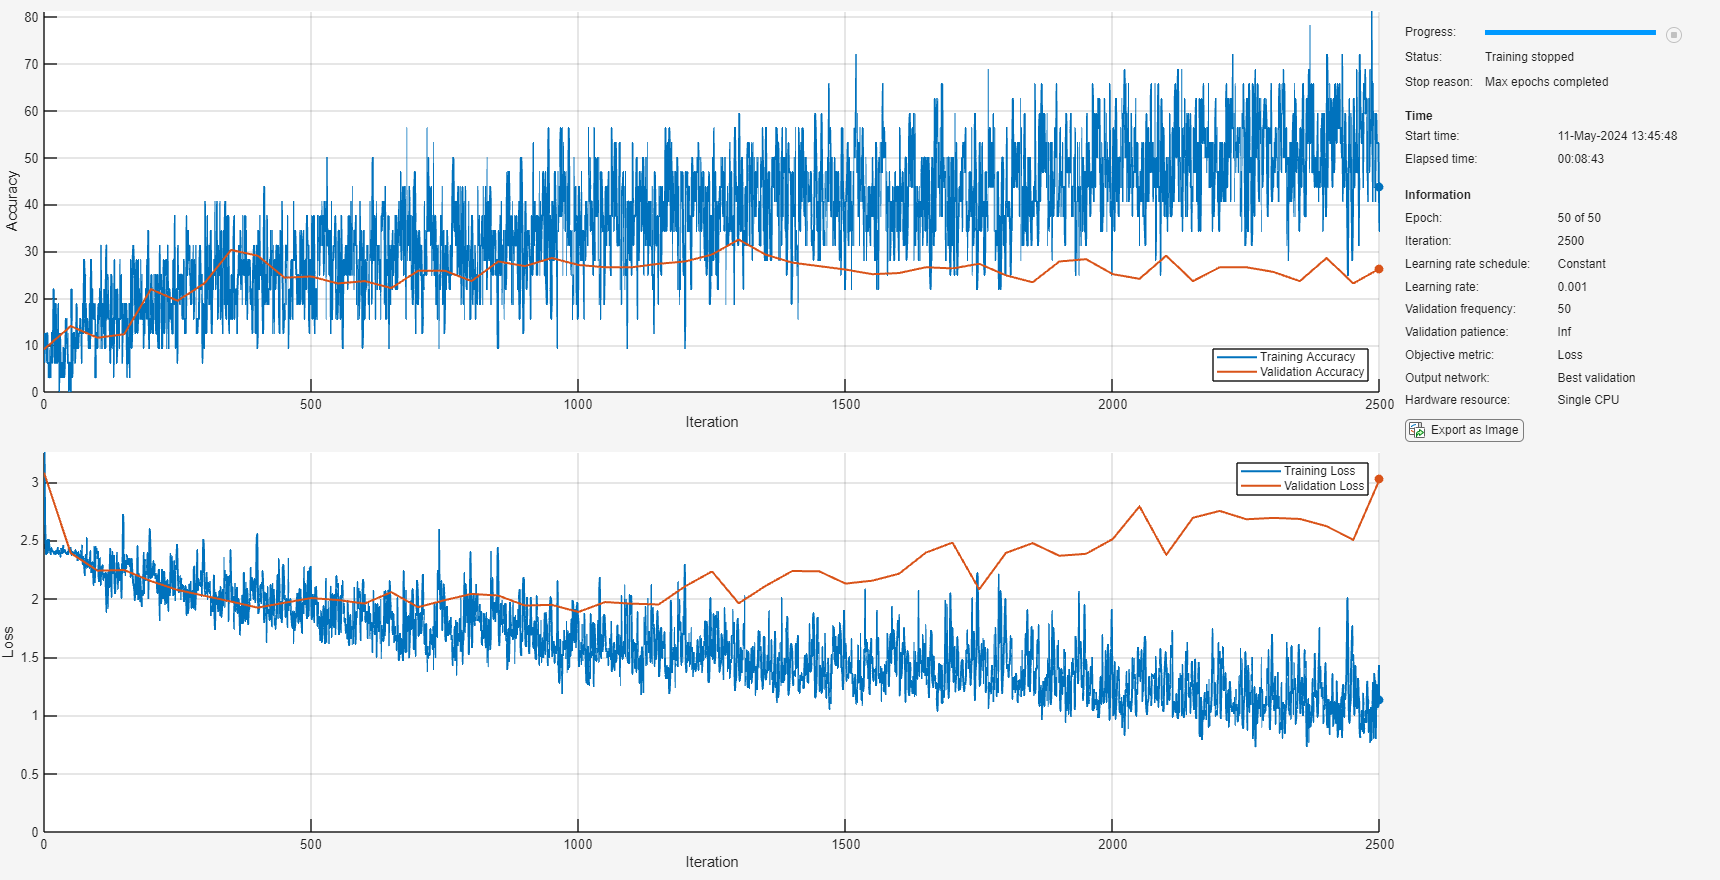

trained_net =   dlnetwork with properties:

         Layers: [71×1 nnet.cnn.layer.Layer]
    Connections: [78×2 table]
     Learnables: [56×3 table]
          State: [0×3 table]
     InputNames: {'imageinput'}
    OutputNames: {'prob_flatten'}
    Initialized: 1

  View summary with summary.


options = trainingOptions('adam',...
    'MiniBatchSize',32,...
    'MaxEpochs',50,...
    'Verbose',1,...
    'ExecutionEnvironment','auto',...
    'Plots','training-progress', ...
    'ValidationData',testDS, ...
    'InitialLearnRate',0.001,'Metrics','accuracy','ValidationFrequency',10 ...
    );
trained_net = trainnet(trainDS,net_1,"crossentropy",options)

% all data
% data = image;
% label = categorical(repmat(["fist1" ;"fist0"],nSample/2,1));
% % spilt
% Xtrain = data(:,:,:,rndIdx(1:nTrainData));
% Ytrain = label(rndIdx(1:nTrainData));
% Xtest = data(:,:,:,rndIdx(nTrainData+1:end));
% Ytest = label(rndIdx(nTrainData+1:end));
% plot(layerGraph(layers))

layers = [
    imageInputLayer(imgSize)
    % image3dInputLayer([225 225 48 1])
    % groupedConvolution2dLayer(3,10,16,"Name","gconv1")
    convolution2dLayer(3,36)
    
    reluLayer
    maxPooling2dLayer(2)

    convolution2dLayer(3,18)
    
    reluLayer
    maxPooling2dLayer(2)

    dropoutLayer(0.5)

    fullyConnectedLayer(10)
    fullyConnectedLayer(nClass)
    % softmaxLayer
    classificationLayer
    ];

options = trainingOptions('adam',...
    'MiniBatchSize',32,...
    'MaxEpochs',50,...
    'Verbose',1,...
    'ExecutionEnvironment','auto',...
    'Plots','training-progress', ...
    'ValidationData',testDS, ...
    'InitialLearnRate',0.001...
    );

% trainedNet = trainnet(trainDS,layers,"crossentropy",options);
net = trainNetwork(trainDS,layers,options);

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       12.50% |       19.64% |       9.3151 |       3.7418 |          0.0010 |
|       3 |          50 |       00:00:11 |        9.38% |       10.12% |  -4.4046e-01 |  -4.9865e-01 |          0.0010 |
|       5 |         100 |       00:00:17 |        3.12% |        7.74% |  -7.4075e-01 |  -7.7328e-01 |          0.0010 |
|       8 |         150 |       00:00:25 |       18.75% |        7.14% |  -1.6455e+00 |  -

% trainedNet = trainNetwork(Xtrain,Ytrain,layers,options);
% mean(classify(trainedNet,testDS) == Ytest)


[Ypred,p] = classify(trainedNetwork_2,testDS);

Unrecognized function or variable 'testDS'.

mean(classify(trainedNetwork_3,trainDS)==trainDS.Labels)*100
mean(Ypred==testDS.Labels)*100
confusionchart(testDS.Labels,Ypred)

datastoreFunc(allImage.Files{1})

ans = 64×64×48 uint8 array
ans(:,:,1) =

     3     4     5     5     4     4     7     9    23    38    56    71    80    77    62    46    25    12    11    28    41    44    49    57    68    75    71    51    28    30    58    86   107   118   113    92    82    94   106   108   102    79    53    41    46    69   106   137   162   164   151   127   116   127   144   154   143   122    89    56    31    16     9     6
     2     3     4     4     3     4     6     9    22    37    56    72    81    79    64    49    30    18    16    30    39    39    43    52    69    76    77    61    43    44    68    93   114   119   106    78    65    80   101   109   100    82    61    50    54    74   109   138   165   165   143   107    91   110   139   154   146   125    91    56    30    14     6     3
     1     2     3     2     1     2     5     8    21    36    56    72    82    81    67    52    37    27    25    33    34    29    32    43    65    75    81    74    63    64    82   

function img = myDatastoreFunc(fileName)
    imgFormatName = extractAfter(fileName,'.');
    imgAndChannel = extractBetween(fileName,'img_','.');
    imgNumber = extractBefore(imgAndChannel,'_');
    imgGroupName = extractBefore(fileName,strcat('img_',imgNumber));
    imgGroupName = strcat(imgGroupName,strcat('img_',imgNumber,'_'));
    for ch = 1:16
        img(:,:,ch) = imread(string(imgGroupName) + ch + "." + string(imgFormatName));
    end
end